# **ACM/IDS 104 - Problem Set 3 - MATLAB Problems**

*Before writing your MATLAB code, it is always good practice to get rid of any leftover variables and figures from previous scripts.*

clc; clear; close all;

## **Problem 3 (10 points) The K-Means Algorithm for Clustering**

In this problem, we will be implementing the K-Means Algorithm for clustering vectors in $\mathbb{R}^2$. To start, let us load and visualize our dataset.

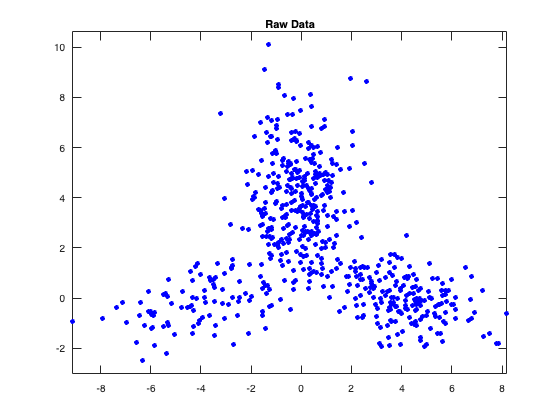

load clustering_data.mat
figure;
plot(x(:,1),x(:,2),'.b','MarkerSize',15);
title("Raw Data")
axis equal;

rng(2016); % for reproducibility

## **Part (a) The Algorithm**

In this part, we will implement the algorithm for $K=3$, which seems to be a reasonable number of clusters for this dataset. Show the clusters after the 1st, 5th, 10th and last iteration. This will illustrate the cluster evolution as the algorithm runs. $\texttt{subplot()}$ is very useful here.

To further aid our understanding of the algorithm, we will be keeping track of a few things:

- Keep track of the evolution of the representatives for each cluster. You can do so by updating the variable $\texttt{z}$ after each iteration.

- Keep track of the objective function value at each iteration.

Once you are done implementing the algorithm, feel free to change the value of $\texttt{K}$ and see how the clusterings are altered.

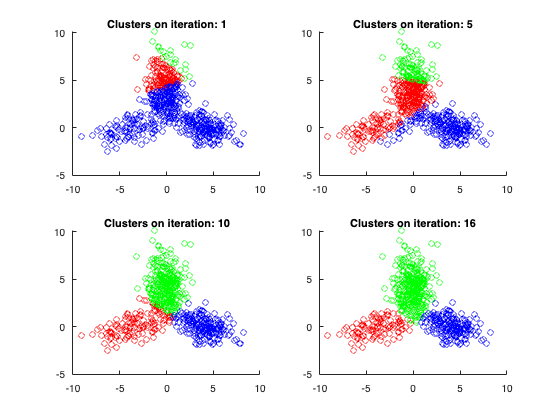

%{
Some useful setup done for you
%}
K = 3; % number of clusters
n = length(x); % number of vectors
c = zeros(n, 1); % clustering : c(i) is the cluster number for vector x(i, :)
iter = 0; % iteration number
z = datasample(x, K); % initial representatives

%{
Step 1: Partitioning into clusters given our initial representatives
%}
for i = 1:n
    c_min = -1;
    dist_min = Inf;
    for k = 1:K
        d = norm(x(i, :) - z(k, :)); 
        %{calculating distance from initial centroids
        if d < dist_min
            c_min = k;
            dist_min = d;
        end
    end
    %{classifying the point based on the closest centroid
    c(i) = c_min;
end
%{
Increment the iteration number
Update the objective function
%}
plots_done = 1;
objective_new = [];
z_prev = 0;

journey1 = zeros(0,2);
journey2 = zeros(0,2);
journey3 = zeros(0,2); %{initializing jounreys for cluster centroids 


while z_prev ~= z %{while there is still a change in the hypothesis
    z_prev = z(:, :);
    % Incrementing the iteration number, updating cluster centroids
    iter = iter + 1;
    for k = 1:K
        x_k = x(c == k, :); %{all the x that were classified under cluster k
        if ~isempty(x_k)
            z(k, :) = mean(x_k); %{new k is the mean of all these x
        end
    end
    journey1 = [journey1; z(1, :)];
    journey2 = [journey2; z(2, :)];
    journey3 = [journey3; z(3, :)]; %{keep track of centroid journeys after each update
    for i = 1:n
        c_min = 10;
        dist_min = Inf;
        for k = 1:K
            d = norm(x(i, :) - z(k, :));
            if d < dist_min
                c_min = k;
                dist_min = d;
            end
        end
        c(i) = c_min; %{reclassifying points based on new centroid positions
    end

    p_tot = 0;
    for k = 1:K
        x_k = x(c == k, :);
        for i = 1:length(x_k)
            p_tot = p_tot + (norm(x_k(i, :) - z(k, :))^2);
        end
    end
    p_tot = p_tot/n;

    objective_new = [objective_new, p_tot]; %{appending the new objective

    colors = ['r', 'g', 'b'];

    if ismember(iter,[1,5,10,16]) %{if we have reached an 
        subplot(2, 2, plots_done);
        hold on;
        for k = 1:K
            x_k = x(c == k, :);
            color = colors(k);
            scatter(x_k(:, 1), x_k(:, 2), 30, color);
        end
        title(['Clusters on iteration: ' num2str(iter)]);
        hold off;
        plots_done = plots_done + 1;

    end
end

## **Part (b) Evolution of Representatives**

Now, let us see the dynamics of the representatives. Plot the original (raw) data and the trajectories of the cluster representatives in one figure. $\texttt{squeeze()}$ might be useful here.

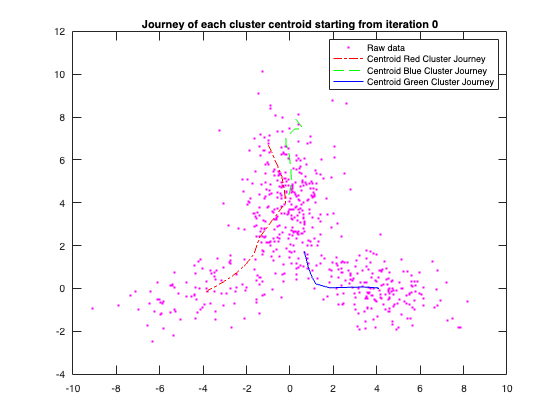

figure
plot(x(:, 1), x(:, 2), '.m', journey1(:, 1), journey1(:, 2), '-.r', journey2(:, 1), journey2(:, 2), '--g', journey3(:, 1), journey3(:, 2), '-b')
legend('Raw data', 'Centroid Red Cluster Journey', 'Centroid Blue Cluster Journey', 'Centroid Green Cluster Journey');
title('Journey of each cluster centroid starting from iteration 0')

## **Part (c) Objective Function**

Plot the values of the objective function against the iteration number. Does the trend match what we expect? Report the minimum value of the objective function using $\texttt{disp()}$.

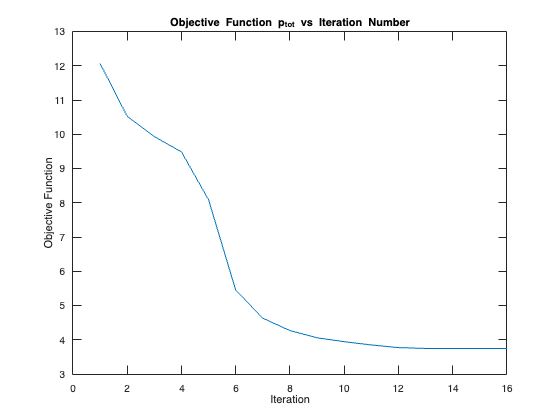

figure;
plot(1:iter, objective_new);
title("Objective Function p_tot vs Iteration Number");
xlabel("Iteration");
ylabel("Objective Function");

final_list = objective_new(end, :);
disp(strcat('Smallest value of objective function is = ', num2str(final_list(16))));

Smallest value of objective function is =3.742


disp(iter);

    16



## **Part (d) Comparing with **$\texttt{kmeans()}$

The K-means algorithm is a very popular clustering algorithm and it is often used in various applications. As such, it is implemented in most numerical software packages. In MATLAB, it exists as the built-in function $\texttt{kmeans()}$. In the simplest form, $\texttt{idx = kmeans(X, k)}$ performs K-means clustering to partition the rows in the data matrix $\texttt{X}$ into $\texttt{k}$ clusters, and returns a vector $\texttt{idx}$ containing cluster indices for each row. To compare your implementation with the built-in one, plot the clustering your obtained in (a) and the clustering obtained by using $\texttt{kmeans()}$.


plots_done = 1

plots_done = 1

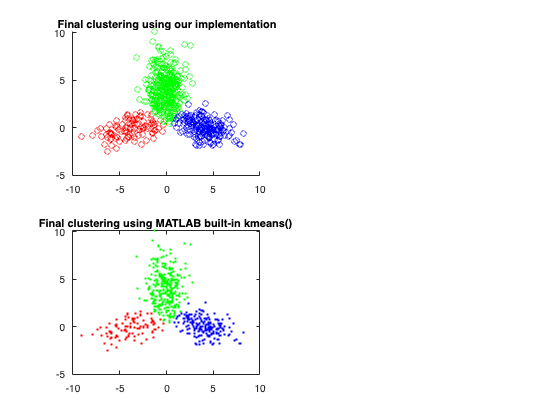

subplot(2, 2, plots_done);
hold on;
for k = 1:K
    x_k = x(c == k, :);
    color = colors(k);
    scatter(x_k(:, 1), x_k(:, 2), 30, color);
end
title('Final clustering using our implementation');
hold off;
builtinplot = subplot(2, 2, 3);
idx = kmeans(x, K);
cluster1points = zeros(0, 2);
cluster2points = zeros(0, 2);
cluster3points = zeros(0, 2);
for i = 1:n
    vector = x(i, :);
    if idx(i) == 1
        cluster1points = [cluster1points; vector];
    end
    if idx(i) == 2
        cluster2points = [cluster2points; vector];
    end
    if idx(i) == 3
        cluster3points = [cluster3points; vector];
    end
end
plot(builtinplot, cluster1points(:, 1), cluster1points(:, 2), '.r', cluster2points(:, 1), cluster2points(:, 2), '.b', cluster3points(:, 1), cluster3points(:, 2), '.g');
title('Final clustering using MATLAB built-in kmeans() ');

## **Problem 5 (10 points) Gram Matrices for Text Classification**

Gram matrices are used in many different applications. Here is a simple example of application to classification of text documents. Suppose we have a collection of $n$ text documents and we want to measure similarity between them. First, we predefine a list of words (the "dictionary'') $w_1,w_2,w_3,\cdots , w_m$ appearing in the documents. Then, for each text $i$ we construct a vector $x_i\in\mathbb{R}^m$ whose $j^{\text{th}}$ component is the number of times the word $w_j$ appears in the text. This way, each text is represented as a vector in $\mathbb{R}^m$. This representation is often referred to as the "bag of words" representation. 

Let $\langle\cdot,\cdot\rangle$ be the usual dot product in $\mathbb{R}^m$ and $\|\cdot\|$ be the Euclidean norm. Let us normalize all vectors $z_i = \frac{x_i}{\|x_i\|}$ and define:


$$Z = [z_1\cdots z_n]\in\mathbb{M}_{m\times n}$$


Let $G$ be the Gram matrix associated with $z_1\cdots z_n$:


$$G = Z^TZ\in \mathbb{M}_{n\times n}$$


Since all $z_i$ are unit vectors:


$$G_{ij}=z_i^Tz_j=\|z_i\|\|z_j\|\cos\theta_{ij}=\cos\theta_{ij}$$


where $\theta_{ij}$is the angle between $z_i$ and $z_j$, which of course is the same as the angle between $x_i$ and $x_j$. This is widely use as a *measure of similarity* between documents. Hence, the more similar two texts $i$ and $j$ are, the closer $G_{ij}$ is to 1.

Now, let us apply this method to real texts. The task is to compare the text of the US Constitution ([found here](https://www.constituteproject.org/constitution/United_States_of_America_1992)) with the Wikipedia pages of Bernie Sanders, Hillary Clinton, Donald Trump, Ted Cruz, and John Kasich, and to find the page which is "closest" to the Constitution.

## Part (a) Setup

To start, we will define a list of $m=10$ words. To find the most "relevant words", copy the text of the Constitution and paste it into a word-cloud generator ([such as this one](http://worditout.com/word-cloud/make-a-new-one)). High frequency words appear large and we can form the dictionary from these words. Note that common sense is needed: words like "amendment'' and "section'' would appear large, but it makes no sense to include them into the dictionary. Also, it makes sense to include "United States'' as a single "word'', not two separate words, etc. But you are free to chose your own dictionary. In the code box below, please fill out the dictionary with your chosen words.

%{
DICTIONARY:
1) president
2) representatives
3) congress
4) members
5) office
6) executive
7) legislative
8) senators
9) majority
10) United States
%}

## Part (b) Fun

With your specified dictionary, let us see which Wikipedia page is closest. First, construct $n=6$ vectors (as specified above), one for each Wikipedia page and one for the Constitution. No need to get fancy here; just go to the related page and search for the number of occureneces of the words in your dictionary. Put all your results in a column vector for each candidate:

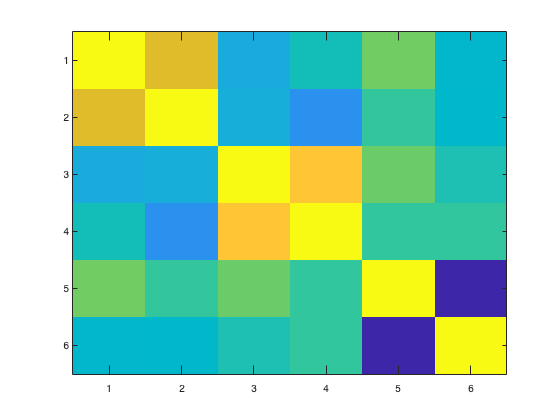

%{Creating the dictionaries using ctrl + find to get the occurences
constitution = [ 121 31 62 10 57 16 2 13 14 89 ];
sanders = [ 91 17 61 20 29 0 2 7 3 58 ];
clinton = [ 119 4 25 14 27 0 0 7 3 48 ];
trump = [ 181 7 40 12 50 32 0 0 11 75 ];
cruz = [ 101 1 35 5 21 3 0 18 9 76 ];
kasich = [ 69 20 27 12 23 10 2 7 3 17 ];

%{ Normalising these vectors
constitution = constitution/norm(constitution);
sanders = sanders/norm(sanders);
clinton = clinton/norm(clinton);
trump = trump/norm(trump);
cruz = cruz/norm(cruz);
kasich = kasich/norm(kasich);


%{
Construct the Gram matrix G as discussed
%}
Z = zeros(0, 10);
Z = [Z; constitution];
Z = [Z; sanders];
Z = [Z; clinton];
Z = [Z; trump];
Z = [Z; cruz];
Z = [Z; kasich];
Z = Z';

G = Z' * Z;

maxind = 0;
max = 0;
for i = 2:6

    cos = G(i, 1);
    if cos > max
        max = cos;
        maxind = i;
    end
end


%{

Bernie Sanders


You can visualize G by uncommenting the following lines of code
%}
figure;
imagesc(G);


%{
Find the page closest to the Constitution text and report your
answer using disp()
%}
if maxind == 2
    disp('Bernie Sanders');
end
if maxind == 3
    disp('Hillary Clinton');
end
if maxind == 4
    disp('Donald Trump');
end
if maxind == 5
    disp('Ted Cruz');
end
if maxind == 6
    disp('John Kasich');
end

Submit the obtained result to the corresponding piazza poll. Remember: this is not about your political preferences, it is about your data analysis :)